# Respuesta en el tiempo - Sistemas de segundo orden.

Autor: ALEXANDER VASCO OROZCO 

## Resumen

En la ingeniería de control los sistemas de segundo orden tienen una relevancia importante, debido a que, gracias a este tipo de sistemas, es posible analizar y proyectar lazos cerrados de control.*.*

## Objetivos de Aprendizaje

Analiza la respuesta transitoria en el tiempo de los sistemas de segundo orden dependiendo de la variación de sus características.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

Los sistemas de segundo orden son todos aquellos que tienen dos polos y están representados típicamente por ecuaciones diferenciales ordinarias de segundo orden. Su función de trasferencia es:


$$g\left(s\right)=\frac{{\omega_n }^2 }{{s^2 +2\rho \omega_n s+\omega_n }^2 }$$


clear
clc
s=tf('s');
Rho=0.5;                        % Coeficiente de amortiguamiento, adimensional
wn=1;                           % Frecuencia natural - rad/seg
g=wn^2/(s^2+2*Rho*wn*s+wn^2)    % Función de transferencia de segundo orden

g =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



r1=-Rho*wn+wn*sqrt(1-Rho^2)*i  % Polos deseados

r1 = -0.5000 + 0.8660i

r2=-Rho*wn-wn*sqrt(1-Rho^2)*i  % Polos deseados

r2 = -0.5000 - 0.8660i

## Sección 2: Ejercicio 1

Para graficar la respuesta al escalón y el lugar geometrico de las raices:

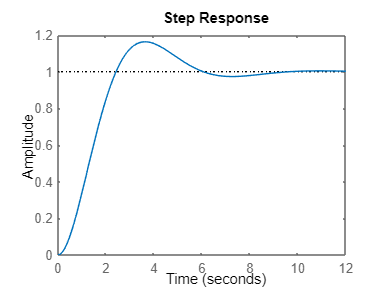

% Celda Rho2=0.8

step(g)

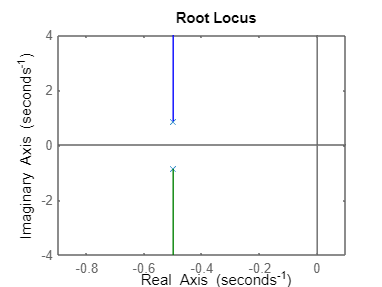

figure
rlocus(g)

## Sección 3: Ejercicio 2

Compare 2 sistemas 

% Celda para adicionar código
close all
wn2=1;
Rho2=0.6;
g2=wn2^2/(s^2+2*Rho2*wn2*s+wn2^2)

g2 =
 
         1
  ---------------
  s^2 + 1.2 s + 1
 
Continuous-time transfer function.



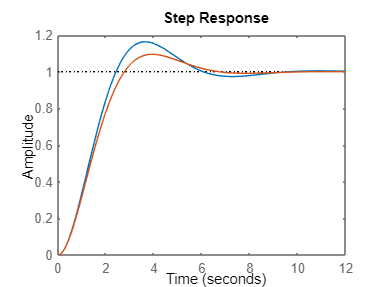

step(g,g2)

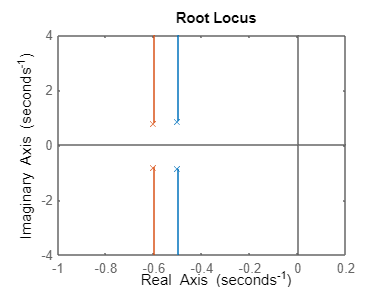

figure
rlocus(g,g2)

## Recursos Adicionales

Revise:

- Pérez Vidal, C., Gracia Calandín, L. I. (2005). Modelado de sistemas dinámicos. Aplicaciones. España: Editorial Club Universitario. 

y complemente:

https://controlautomaticoeducacion.com/control-realimentado/sistemas-de-segundo-orden/

## Referencias 

- Ortiz Moctezuma, M. B. (2015). Sistemas dinámicos en tiempo continuo: Modelado y simulación. España: OmniaScience.

- Barreira, L - Valls, C (2013). Sistemas dinámicos: una introducción. ISBN: 9788415581567. Editorial: Delta Publicaciones. – Ebook.